clear; clc; close all;
repo_root = project_root();
addpath(fullfile(repo_root, 'shared', 'matlab'), '-begin');
add_project_paths(repo_root);
cfg = struct();
cfg.analysis_dir = fullfile(repo_root, 'outputs', 'publication_analysis');
cfg.task_stems = {'dynamical_systems_vanderpol', 'regression_yacht', 'classification_BC'};
cfg.task_labels = {'Van der Pol', 'Yacht', 'Breast cancer'};
cfg.display_seed = 1;
cfg.minimum_summary_seed_count = 1; % Raise to 3 when all SPSA seeds are tested.
cfg.expected_recurrent_mode = 'low_rank';
cfg.phase_stride = 5;
cfg.time_window_s = 10;
cfg.rate_distribution_y_scale = 'log';
cfg.violin_max_width = .30;
cfg.violin_face_alpha = .85;
cfg.violin_kde_points = 600;
cfg.font_name = 'Arial';
cfg.tick_font_size = 12;
cfg.label_font_size = 15;
cfg.title_font_size = 18;
cfg.axes_line_width = .75;
cfg.tick_direction = 'out';
cfg.show_grid = true;
cfg.line_width = 1.0;
cfg.network_color = [0 0 0];
cfg.truth_color = [0.8660 0.3290 0.0000];
cfg.rate_color = [0.20 0.58 0.38];
cfg.active_color = [0.42 0.48 0.58];
cfg.median_color = [0 0 0];
cfg.summary_point_color = [0 0 0];
cfg.figure_size_in = [12.0 8.2];
cfg.figure_color = 'w';
cfg.panel_positions = {[.005 .515 .485 .460], [.510 .515 .485 .460], ...
    [.005 .015 .485 .455], [.510 .015 .485 .455]};
cfg.panel_letters = {'A', 'B', 'C', 'D'};
cfg.panel_letter_offset = [0 .025];
cfg.panel_letter_size = cfg.title_font_size + 12;

% A: SPSA algorithm schematic
cfg.spsa_axes_position = [.08 .12 .84 .76];
cfg.spsa_title = 'Bias-only SPSA update';
cfg.spsa_trainable_color = [.92 .95 1.00];
cfg.spsa_perturbation_color = [.99 .94 .84];
cfg.spsa_evaluation_color = [.94 .94 .94];
cfg.spsa_update_color = [.88 .96 .90];
cfg.spsa_arrow_color = [.10 .35 .62];
cfg.spsa_box_font_size = cfg.tick_font_size;

% B: Van der Pol example
cfg.vanderpol_network_axes_position = [.10 .62 .34 .29];
cfg.vanderpol_truth_axes_position = [.57 .62 .34 .29];
cfg.vanderpol_time_axes_position = [.10 .20 .81 .22];
cfg.vanderpol_legend_axes_position = [.10 .035 .81 .045];
cfg.vanderpol_network_title = 'Network phase portrait';
cfg.vanderpol_truth_title = 'True-system phase portrait';
cfg.vanderpol_time_title_with_wd = 'Closed-loop time series (phase-portrait WD = %.3g)';
cfg.vanderpol_time_title_without_wd = 'Closed-loop time series';
cfg.vanderpol_phase_x_label = 'x_1';
cfg.vanderpol_phase_y_label = 'x_2';
cfg.vanderpol_time_x_label = 'Time after warmup (s)';
cfg.vanderpol_time_y_label = 'x_1';
cfg.vanderpol_phase_axis_square = true;
cfg.vanderpol_phase_limits = [];
cfg.vanderpol_time_x_limits = [];
cfg.vanderpol_time_y_limits = [];
cfg.vanderpol_legend_labels = {'Network output', 'True system'};
cfg.vanderpol_legend_location = 'north';
cfg.vanderpol_legend_orientation = 'horizontal';
cfg.vanderpol_legend_box = 'off';
cfg.vanderpol_legend_font_size = cfg.tick_font_size - 1;

% C: firing-rate distributions
cfg.rate_axes_position = [.15 .15 .76 .72];
cfg.rate_title = 'Full-test firing-rate distributions';
cfg.rate_x_label = '';
cfg.rate_y_label = 'Mean firing rate of active neurons (Hz)';
cfg.rate_x_limits = [];
cfg.rate_y_limits = [];
cfg.rate_show_median = true;
cfg.rate_median_half_width = .22;
cfg.rate_median_line_width = 1.1;
cfg.rate_x_tick_label_rotation = 25;

% D: active-neuron fraction
cfg.active_axes_position = [.15 .15 .76 .72];
cfg.active_title = 'Active-neuron fraction across saved seeds';
cfg.active_x_label = '';
cfg.active_y_label = 'Active neurons (%)';
cfg.active_x_limits = [];
cfg.active_y_limits = [0 100];
cfg.active_bar_width = .62;
cfg.active_errorbar_color = [0 0 0];
cfg.active_errorbar_line_width = 1.0;
cfg.active_point_marker = 'o';
cfg.active_point_size = 4;
cfg.active_point_jitter_width = .11;
cfg.active_x_tick_label_rotation = 25;

cfg.export_png = true;
cfg.export_png_dpi = 500;
cfg.output_dir = fullfile(repo_root, 'shared', 'plotting', 'publication_figures', ...
    'generated_spsa_figure');
cfg.output_filename = 'spsa_network_publication_figure.png';
[analyses, source_files] = load_spsa_analyses(cfg);

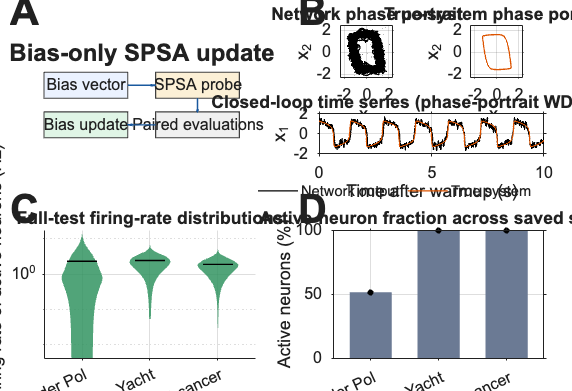

Exported SPSA publication figure PNG: /Users/kaimason/Library/CloudStorage/OneDrive-UniversityofCalgary/Neural_networks_bias_learning/Spiking_neural_networks/SE adLIF/For Publication/GitHub_V2_multiple_architectures_working/shared/plotting/publication_figures/generated_spsa_figure/spsa_network_publication_figure.png


data = prepare_spsa_data(analyses, cfg);
fig = figure('Color', cfg.figure_color, 'Units', 'inches', 'Position', [1 1 cfg.figure_size_in]);
for ii = 1:4
    add_panel_label(fig, cfg.panel_letters{ii}, cfg.panel_positions{ii}, cfg);
end
render_spsa_panel(fig, cfg.panel_positions{1}, cfg);
render_vanderpol_panel(fig, cfg.panel_positions{2}, data.vanderpol, cfg);
render_rate_panel(fig, cfg.panel_positions{3}, data.summary, cfg);
render_active_fraction_panel(fig, cfg.panel_positions{4}, data.summary, cfg);
hide_axes_toolbars(fig);

if cfg.export_png
    if exist(cfg.output_dir, 'dir') ~= 7, mkdir(cfg.output_dir); end
    output_file = fullfile(cfg.output_dir, cfg.output_filename);
    set(fig, 'PaperPositionMode', 'auto', 'InvertHardcopy', 'off');
    print(fig, output_file, '-dpng', sprintf('-r%d', cfg.export_png_dpi));
    fprintf('Exported SPSA publication figure PNG: %s\n', output_file);
end

fprintf('Loaded SPSA analyses:\n');

Loaded SPSA analyses:


fprintf('  %s\n', source_files{:});

  /Users/kaimason/Library/CloudStorage/OneDrive-UniversityofCalgary/Neural_networks_bias_learning/Spiking_neural_networks/SE adLIF/For Publication/GitHub_V2_multiple_architectures_working/outputs/publication_analysis/dynamical_systems_vanderpol_spsa_gpu_test_analysis_20260721_145540_309.mat
  /Users/kaimason/Library/CloudStorage/OneDrive-UniversityofCalgary/Neural_networks_bias_learning/Spiking_neural_networks/SE adLIF/For Publication/GitHub_V2_multiple_architectures_working/outputs/publication_analysis/regression_yacht_spsa_gpu_test_analysis_20260721_162108_597.mat
  /Users/kaimason/Library/CloudStorage/OneDrive-UniversityofCalgary/Neural_networks_bias_learning/Spiking_neural_networks/SE adLIF/For Publication/GitHub_V2_multiple_architectures_working/outputs/publication_analysis/classification_BC_lowrank_SPSA_GPU_primary_seed001_continued_45000epochs_gpu_test_analysis_20260721_144949_793.mat




function [analyses, source_files] = load_spsa_analyses(cfg)
n_tasks = numel(cfg.task_stems);
if numel(cfg.task_labels) ~= n_tasks
    error('spsaFigure:taskLabels', 'task_stems and task_labels must have equal length.');
end
analyses = cell(1, n_tasks);
source_files = cell(1, n_tasks);
for ii = 1:n_tasks
    files = dir(fullfile(cfg.analysis_dir, sprintf('%s*_test_analysis_*.mat', cfg.task_stems{ii})));
    if isempty(files)
        error('spsaFigure:missingAnalysis', ['No saved SPSA analysis was found for %s. ' ...
            'Run the dedicated SPSA test script and allow it to export publication analysis data.'], cfg.task_labels{ii});
    end
    [~, order] = sort([files.datenum], 'descend');
    for jj = order
        candidate = fullfile(files(jj).folder, files(jj).name);
        try
            A = load_publication_analysis_file(candidate);
            validate_spsa_analysis(A, cfg, cfg.task_stems{ii});
            analyses{ii} = A;
            source_files{ii} = candidate;
            break;
        catch ME
            warning('spsaFigure:skippingAnalysis', 'Skipping %s: %s', files(jj).name, ME.message);
        end
    end
    if isempty(analyses{ii})
        error('spsaFigure:noUsableAnalysis', 'No usable SPSA analysis was found for %s.', cfg.task_labels{ii});
    end
end
end

function validate_spsa_analysis(A, cfg, task_stem)
if ~isstruct(A) || ~isfield(A, 'seeds') || isempty(A.seeds)
    error('spsaFigure:invalidAnalysis', 'Saved analysis has no seed data.');
end
task_id = lower(char(field_or(A, 'task_id', '')));
if ~contains(task_id, lower(task_stem))
    error('spsaFigure:wrongTask', 'Saved task ID "%s" does not match "%s".', task_id, task_stem);
end
for ii = 1:numel(A.seeds)
    seed = A.seeds(ii);
    if ~isfield(seed, 'architecture') || ~isfield(seed, 'neural_activity') || ~isfield(seed, 'test')
        error('spsaFigure:missingFields', 'Saved seed %d lacks publication plotting fields.', ii);
    end
    provenance = lower(strjoin({char(field_or(A, 'trained_model_backend', '')), ...
        char(field_or(seed, 'train_backend', '')), char(field_or(seed, 'model_file', ''))}, ' '));
    if ~contains(provenance, 'spsa')
        error('spsaFigure:notSPSA', 'Saved seed %d is not identified as SPSA-trained.', ii);
    end
    mode = lower(char(field_or(seed.architecture, 'recurrent_mode', '')));
    if ~isempty(cfg.expected_recurrent_mode) && ~strcmp(mode, cfg.expected_recurrent_mode)
        error('spsaFigure:wrongArchitecture', 'Expected recurrent mode "%s", found "%s".', ...
            cfg.expected_recurrent_mode, mode);
    end
end
end

function data = prepare_spsa_data(analyses, cfg)
vdp_seed = select_seed(analyses{1}, cfg.display_seed);
[pred, truth] = first_closed_loop_trajectory(vdp_seed.test);
n = min(size(pred, 1), size(truth, 1));
if n < 2 || size(pred, 2) < 2 || any(~isfinite(pred(1:n, :)), 'all') || any(~isfinite(truth(1:n, :)), 'all')
    error('spsaFigure:badVanderpolTrajectory', 'Van der Pol saved trajectory is missing or non-finite.');
end
dt = double(field_or(vdp_seed.options, 'dt', 1));
time_index = 1:max(1, round(cfg.phase_stride)):n;
time_keep = (0:n-1).' .* dt <= cfg.time_window_s;
if ~any(time_keep), time_keep(1) = true; end
data.vanderpol = struct('pred', double(pred(time_index, 1:2)), ...
    'truth', double(truth(time_index, 1:2)), 'time', (0:n-1).' .* dt, ...
    'time_pred', double(pred(time_keep, 1)), 'time_truth', double(truth(time_keep, 1)), ...
    'wd', double(field_or(vdp_seed.test, 'wasserstein_distance', NaN)));

summary = struct();
summary.labels = cfg.task_labels;
summary.rates = cell(1, numel(analyses));
summary.active = cell(1, numel(analyses));
for ii = 1:numel(analyses)
    display_seed = select_seed(analyses{ii}, cfg.display_seed);
    rate = double(display_seed.neural_activity.mean_firing_rate_by_neuron_hz(:));
    summary.rates{ii} = rate(isfinite(rate) & rate > 0);
    active = nan(1, numel(analyses{ii}.seeds));
    for jj = 1:numel(analyses{ii}.seeds)
        active(jj) = double(analyses{ii}.seeds(jj).neural_activity.active_fraction_percent);
    end
    summary.active{ii} = active(isfinite(active));
    if numel(summary.active{ii}) < cfg.minimum_summary_seed_count
        error('spsaFigure:insufficientSeeds', '%s has fewer than %d usable saved seed(s).', ...
            cfg.task_labels{ii}, cfg.minimum_summary_seed_count);
    end
end
data.summary = summary;
end

function seed = select_seed(A, requested_seed)
seed_values = arrayfun(@(x) double(field_or(x, 'init_seed', NaN)), A.seeds);
index = find(seed_values == requested_seed, 1);
if isempty(index)
    error('spsaFigure:missingDisplaySeed', 'Requested seed %d is unavailable. Available seeds: %s.', ...
        requested_seed, num2str(seed_values));
end
seed = A.seeds(index);
end

function [pred, truth] = first_closed_loop_trajectory(test)
if isfield(test, 'closed_loop') && isstruct(test.closed_loop), test = test.closed_loop; end
if isfield(test, 'pred_norm_by_ic') && isfield(test, 'true_norm_by_ic')
    pred = first_cell(test.pred_norm_by_ic); truth = first_cell(test.true_norm_by_ic);
elseif isfield(test, 'pred_norm') && isfield(test, 'true_norm')
    pred = test.pred_norm; truth = test.true_norm;
else
    error('spsaFigure:missingTrajectory', 'No closed-loop prediction and truth trajectory was saved.');
end
end

function value = first_cell(value)
if iscell(value)
    if isempty(value), value = zeros(0, 0); else, value = value{1}; end
end
end

function render_spsa_panel(fig, panel_position, cfg)
ax = axes_in_panel(fig, panel_position, cfg.spsa_axes_position);
set(ax, 'XLim', [0 1], 'YLim', [0 1], 'Visible', 'off'); hold(ax, 'on');
draw_spsa_box(ax, [.08 .51 .36 .19], 'Bias vector', cfg.spsa_trainable_color, cfg);
draw_spsa_box(ax, [.56 .51 .36 .19], 'SPSA probe', cfg.spsa_perturbation_color, cfg);
draw_spsa_box(ax, [.56 .22 .36 .19], 'Paired evaluations', cfg.spsa_evaluation_color, cfg);
draw_spsa_box(ax, [.08 .22 .36 .19], 'Bias update', cfg.spsa_update_color, cfg);
draw_spsa_arrow(ax, [.44 .605], [.56 .605], cfg.spsa_arrow_color, '-', cfg);
draw_spsa_arrow(ax, [.74 .51], [.74 .41], cfg.spsa_arrow_color, '-', cfg);
draw_spsa_arrow(ax, [.56 .315], [.44 .315], cfg.spsa_arrow_color, '-', cfg);
text(ax, .50, .84, cfg.spsa_title, 'FontName', cfg.font_name, 'FontSize', cfg.title_font_size, ...
    'FontWeight', 'bold', 'HorizontalAlignment', 'center');
hold(ax, 'off');
end

function draw_spsa_box(ax, position, label, color, cfg)
rectangle(ax, 'Position', position, 'FaceColor', color, 'EdgeColor', [.25 .25 .25], 'LineWidth', .8);
text(ax, position(1)+position(3)/2, position(2)+position(4)/2, label, ...
    'FontName', cfg.font_name, 'FontSize', cfg.spsa_box_font_size, ...
    'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', 'Interpreter', 'none');
end

function draw_spsa_arrow(ax, start_point, end_point, color, style, cfg)
delta = end_point - start_point;
quiver(ax, start_point(1), start_point(2), delta(1), delta(2), 0, ...
    'Color', color, 'LineStyle', style, 'LineWidth', cfg.line_width, 'MaxHeadSize', .55);
end

function render_vanderpol_panel(fig, panel_position, data, cfg)
limits = padded_limits([data.pred(:,1); data.truth(:,1); data.pred(:,2); data.truth(:,2)]);
if ~isempty(cfg.vanderpol_phase_limits), limits = cfg.vanderpol_phase_limits; end
ax_network = axes_in_panel(fig, panel_position, cfg.vanderpol_network_axes_position);
plot(ax_network, data.pred(:,1), data.pred(:,2), 'Color', cfg.network_color, 'LineWidth', cfg.line_width);
if cfg.vanderpol_phase_axis_square, axis(ax_network, 'square'); end
xlim(ax_network, limits); ylim(ax_network, limits); grid(ax_network, on_off(cfg.show_grid));
xlabel(ax_network, cfg.vanderpol_phase_x_label); ylabel(ax_network, cfg.vanderpol_phase_y_label);
title(ax_network, cfg.vanderpol_network_title, 'FontSize', cfg.title_font_size); format_axes(ax_network, cfg);
ax_truth = axes_in_panel(fig, panel_position, cfg.vanderpol_truth_axes_position);
plot(ax_truth, data.truth(:,1), data.truth(:,2), 'Color', cfg.truth_color, 'LineWidth', cfg.line_width);
if cfg.vanderpol_phase_axis_square, axis(ax_truth, 'square'); end
xlim(ax_truth, limits); ylim(ax_truth, limits); grid(ax_truth, on_off(cfg.show_grid));
xlabel(ax_truth, cfg.vanderpol_phase_x_label); ylabel(ax_truth, cfg.vanderpol_phase_y_label);
title(ax_truth, cfg.vanderpol_truth_title, 'FontSize', cfg.title_font_size); format_axes(ax_truth, cfg);
ax_time = axes_in_panel(fig, panel_position, cfg.vanderpol_time_axes_position);
time_keep = data.time <= cfg.time_window_s;
plot(ax_time, data.time(time_keep), data.time_pred, 'Color', cfg.network_color, 'LineWidth', cfg.line_width); hold(ax_time, 'on');
plot(ax_time, data.time(time_keep), data.time_truth, 'Color', cfg.truth_color, 'LineWidth', cfg.line_width); hold(ax_time, 'off');
grid(ax_time, on_off(cfg.show_grid));
if ~isempty(cfg.vanderpol_time_x_limits), xlim(ax_time, cfg.vanderpol_time_x_limits); end
if ~isempty(cfg.vanderpol_time_y_limits), ylim(ax_time, cfg.vanderpol_time_y_limits); end
xlabel(ax_time, cfg.vanderpol_time_x_label); ylabel(ax_time, cfg.vanderpol_time_y_label);
if isfinite(data.wd), title(ax_time, sprintf(cfg.vanderpol_time_title_with_wd, data.wd), 'FontSize', cfg.title_font_size); else, title(ax_time, cfg.vanderpol_time_title_without_wd, 'FontSize', cfg.title_font_size); end
format_axes(ax_time, cfg);
ax_legend = axes_in_panel(fig, panel_position, cfg.vanderpol_legend_axes_position);
h1 = plot(ax_legend, nan, nan, 'Color', cfg.network_color, 'LineWidth', cfg.line_width); hold(ax_legend, 'on');
h2 = plot(ax_legend, nan, nan, 'Color', cfg.truth_color, 'LineWidth', cfg.line_width); hold(ax_legend, 'off');
legend(ax_legend, [h1 h2], cfg.vanderpol_legend_labels, 'Location', cfg.vanderpol_legend_location, ...
    'Orientation', cfg.vanderpol_legend_orientation, 'Box', cfg.vanderpol_legend_box, ...
    'FontSize', cfg.vanderpol_legend_font_size);
axis(ax_legend, 'off');
end

function render_rate_panel(fig, panel_position, summary, cfg)
ax = axes_in_panel(fig, panel_position, cfg.rate_axes_position); hold(ax, 'on');
for ii = 1:numel(summary.rates)
    values = summary.rates{ii};
    if isempty(values), continue; end
    draw_violin(ax, ii, values, cfg.rate_color, cfg);
    if cfg.rate_show_median
        value = median(values);
        plot(ax, [ii-cfg.rate_median_half_width ii+cfg.rate_median_half_width], [value value], ...
            '-', 'Color', cfg.median_color, 'LineWidth', cfg.rate_median_line_width);
    end
end
hold(ax, 'off'); set(ax, 'YScale', cfg.rate_distribution_y_scale); grid(ax, on_off(cfg.show_grid));
if isempty(cfg.rate_x_limits), xlim(ax, [.45 numel(summary.labels)+.55]); else, xlim(ax, cfg.rate_x_limits); end
if ~isempty(cfg.rate_y_limits), ylim(ax, cfg.rate_y_limits); end
xticks(ax, 1:numel(summary.labels)); xticklabels(ax, summary.labels);
xlabel(ax, cfg.rate_x_label); ylabel(ax, cfg.rate_y_label); title(ax, cfg.rate_title, 'FontSize', cfg.title_font_size);
format_axes(ax, cfg); rotate_labels(ax, cfg.rate_x_tick_label_rotation);
end

function render_active_fraction_panel(fig, panel_position, summary, cfg)
ax = axes_in_panel(fig, panel_position, cfg.active_axes_position);
n = numel(summary.labels); means = nan(1,n); deviations = nan(1,n);
for ii = 1:n
    means(ii) = mean(summary.active{ii});
    if numel(summary.active{ii}) > 1, deviations(ii) = std(summary.active{ii},0); else, deviations(ii) = 0; end
end
bar(ax, 1:n, means, cfg.active_bar_width, 'FaceColor', cfg.active_color, 'EdgeColor', 'none'); hold(ax, 'on');
if any(deviations > 0), errorbar(ax, 1:n, means, deviations, '.', 'Color', cfg.active_errorbar_color, 'LineWidth', cfg.active_errorbar_line_width); end
for ii = 1:n
    offsets = point_offsets(numel(summary.active{ii}), cfg.active_point_jitter_width);
    plot(ax, ii+offsets, summary.active{ii}, 'LineStyle', 'none', 'Marker', cfg.active_point_marker, ...
        'Color', cfg.summary_point_color, 'MarkerFaceColor', cfg.summary_point_color, 'MarkerSize', cfg.active_point_size);
end
hold(ax, 'off'); grid(ax, on_off(cfg.show_grid));
if ~isempty(cfg.active_y_limits), ylim(ax, cfg.active_y_limits); end
if isempty(cfg.active_x_limits), xlim(ax, [.45 n+.55]); else, xlim(ax, cfg.active_x_limits); end
xticks(ax,1:n); xticklabels(ax,summary.labels); xlabel(ax,cfg.active_x_label); ylabel(ax,cfg.active_y_label);
title(ax,cfg.active_title,'FontSize',cfg.title_font_size); format_axes(ax,cfg); rotate_labels(ax,cfg.active_x_tick_label_rotation);
end

function draw_violin(ax, x, values, color, cfg)
if exist('ksdensity', 'file') ~= 2, error('spsaFigure:missingKsdensity', 'ksdensity is required for the violin panel.'); end
positions = linspace(min(values), max(values), cfg.violin_kde_points).';
if numel(values) == 1 || positions(1) == positions(end)
    plot(ax, [x-cfg.violin_max_width x+cfg.violin_max_width], [values(1) values(1)], 'Color', color); return;
end
density = ksdensity(values, positions);
half_width = cfg.violin_max_width .* density(:) ./ max(density);
patch(ax, [x-half_width; flipud(x+half_width)], [positions; flipud(positions)], color, ...
    'FaceAlpha', cfg.violin_face_alpha, 'EdgeColor', 'none');
end

function add_panel_label(fig, label, panel_position, cfg)
annotation(fig, 'textbox', [panel_position(1)+cfg.panel_letter_offset(1) ...
    panel_position(2)+panel_position(4)-cfg.panel_letter_offset(2) .04 .03], ...
    'String', label, 'EdgeColor', 'none', 'FontName', cfg.font_name, ...
    'FontSize', cfg.panel_letter_size, 'FontWeight', 'bold', 'VerticalAlignment', 'middle');
end

function ax = axes_in_panel(fig, panel_position, local_position)
position = [panel_position(1)+local_position(1)*panel_position(3), ...
    panel_position(2)+local_position(2)*panel_position(4), ...
    local_position(3)*panel_position(3), local_position(4)*panel_position(4)];
ax = axes('Parent', fig, 'Units', 'normalized', 'Position', position);
end

function limits = padded_limits(values)
values = double(values(:)); values = values(isfinite(values));
if isempty(values), limits = [-1 1]; return; end
span = max(values)-min(values); if span <= 0, span = max(1,abs(values(1))); end
limits = [min(values)-.05*span max(values)+.05*span];
end

function offsets = point_offsets(n, width)
if n < 2, offsets = zeros(n,1); else, offsets = linspace(-width,width,n).'; end
end

function format_axes(ax, cfg)
set(ax, 'FontName', cfg.font_name, 'FontSize', cfg.tick_font_size, ...
    'LineWidth', cfg.axes_line_width, 'TickDir', cfg.tick_direction);
end

function rotate_labels(ax, angle)
try, xtickangle(ax,angle); catch, set(ax,'XTickLabelRotation',angle); end
end

function value = on_off(flag)
if flag, value = 'on'; else, value = 'off'; end
end

function hide_axes_toolbars(fig)
for ax = findall(fig,'Type','axes').'
    try, ax.Toolbar.Visible = 'off'; catch, end
end
end

function value = field_or(S, field_name, fallback)
if isstruct(S) && isfield(S, field_name) && ~isempty(S.(field_name))
    value = S.(field_name);
else
    value = fallback;
end
end